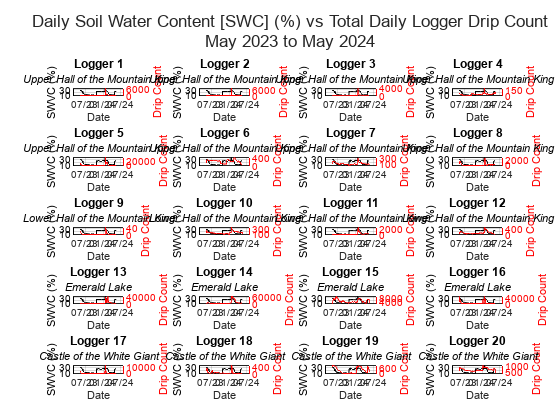

%Rainfall_MM_Daily_Logger_Drip_Count
% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
data = readtable('SWCLogsAllDaily.xlsx');

% Extract dates, rainfall, and drip count data
dates = data{:, 1}; % Time is in column 1
SWVC = data{:, 2}; % Rainfall is in column 2
drip_count = data{:, 3:22}; % Drip count is in columns 3 to 22

% Create a figure with 20 subplots
f = figure; clf;
tiledlayout(5, 4, 'TileSpacing', 'tight'); % 5x4 grid of subplots

% Loop through each drip count column (from 1 to 20)
for i = 1:20
    nexttile; % Move to the next tile/subplot

    yyaxis left;
    plot(dates, SWVC, 'k'); % Plot rainfall on the left axis
    ylabel('SWVC (%)', 'Color', 'k');
    
    yyaxis right;
    plot(dates, drip_count(:, i), 'r'); % Plot drip count for current logger on the right axis
    xlabel('Date');
    ylabel('Drip Count', 'Color', 'r');
    
    % Set title and other properties
    title(['Logger ', num2str(i)], 'FontSize', 9);
    datetick('x', 'mm/yy', 'keepticks');
    xtickangle(0);
    grid on;
    axis padded;
    
    % Set subtitle based on the logger number (customize as needed)
    if i <= 8
        subtitle('Upper Hall of the Mountain King', 'FontSize', 2, 'FontAngle', 'italic');
    elseif i <= 12
        subtitle('Lower Hall of the Mountain King', 'FontSize', 2, 'FontAngle', 'italic');
    elseif i <= 16
        subtitle('Emerald Lake', 'FontSize', 2, 'FontAngle', 'italic');
    else
        subtitle('Castle of the White Giant', 'FontSize', 2, 'FontAngle', 'italic');
    end
    
    % Customize axis colors
    ax = gca;
    ax.YAxis(1).Color = 'k';
    ax.YAxis(2).Color = 'r';
    ax.YAxis(2).Exponent = 0;
end

% Add a global title for all subplots
sgtitle({'\bf Daily Soil Water Content [SWC] (%) vs Total Daily Logger Drip Count', ' May 2023 to May 2024'});
saveas(f, 'Daily SWC Logs.png');  % Saves the current figure